# ZEN vs 時間相関プログラム

POINT = sprintf("x=%d", constant_X);
addpath(genpath("zen"));
zen_matrix = readmatrix(sprintf("zen/%s/%s.txt",DATE, beads_size));
row = find((zen_matrix(:,1) > TIME_SCALE) & (zen_matrix(:,1) < TIME_SCALE*TAU_MAX))

row =     90
    91
    92
    93
    94
    95
    96
    97
    98
    99


zen_matrix_extracted = zen_matrix(row, :)

zen_matrix_extracted =     0.0020    8.8556
    0.0023    8.4859
    0.0025    8.1592
    0.0027    7.8683
    0.0029    7.5972
    0.0031    7.3409
    0.0033    7.0979
    0.0037    6.6619
    0.0041    6.2197
    0.0045    5.7868


TAU_zen = zen_matrix_extracted(:,1); 
COR_zen = zen_matrix_extracted(:,2);

プロット

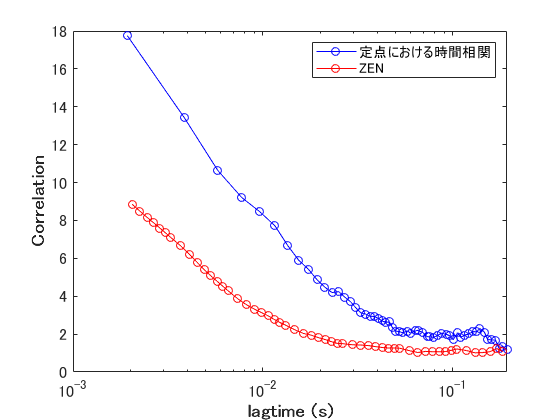

semilogx(TAU,COR, "b-o");
ax = gca; % current axes
ax.FontSize = 12;
xlabel("lagtime (s)", 'FontSize',14,'FontWeight','bold');
ylabel("Correlation", 'FontSize',14,'FontWeight','bold');

hold on;

semilogx(TAU_zen, COR_zen, "r-o")
legend("定点における時間相関", "ZEN", 'Location','northeast');

hold off;
title(sprintf("ZEN vs 時間相関プログラム (ビーズ%s 定点%s)", beads_size, POINT));
saveas(gcf, sprintf("output/zen_%s/%s/range_%s",DATE,POINT,figurename))

そのACFのτ＝０の点を基準に規格化→1~2

COR_normalized = COR-1

COR_normalized =    16.7642   16.7642   16.7642   16.7642   16.7642   16.7642   16.7642   16.7642   16.7642   12.4167   12.4167   12.4167   12.4167   12.4167   12.4167   12.4167   12.4167   12.4167   12.4167   12.4167    9.6380    9.6380    9.6380    9.6380    9.6380    9.6380    9.6380    8.2201    8.2201    8.2201    8.2201    8.2201    8.2201    7.4510    7.4510    7.4510    7.4510    6.7139    6.7139    6.7139    6.7139    5.6776    5.6776    5.6776    4.9003    4.9003    4.9003    4.4234    4.4234    3.8663


COR_zen_normalized = COR_zen -1

COR_zen_normalized =     7.8556
    7.4859
    7.1592
    6.8683
    6.5972
    6.3409
    6.0979
    5.6619
    5.2197
    4.7868


SCALE = COR_zen_normalized(1) / COR_normalized(1)

SCALE = 0.4686

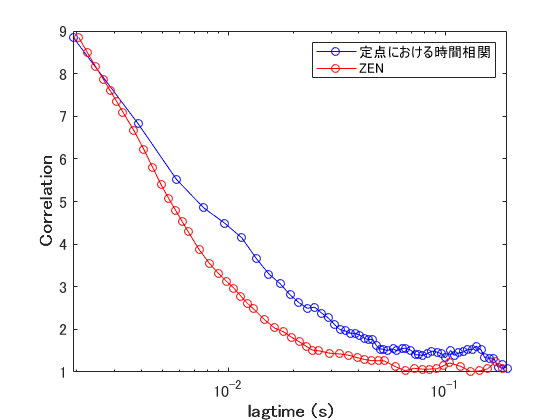

COR_normalized2zen = COR_normalized .* SCALE;

COR_normalized2zen = COR_normalized2zen + 1;
COR_zen_normalized = COR_zen_normalized + 1;

semilogx(TAU, COR_normalized2zen, "b-o")
hold on;
semilogx(TAU_zen, COR_zen_normalized, "r-o")
xlim([TIME_SCALE TIME_SCALE*TAU_MAX])
legend("定点における時間相関", "ZEN", 'Location','northeast');

ax = gca; % current axes
ax.FontSize = 12;
xlabel("lagtime (s)", 'FontSize',14,'FontWeight','bold');
ylabel("Correlation_normalized", 'FontSize',14,'FontWeight','bold');

hold off;
title(sprintf("ZEN vs 時間相関プログラム (ビーズ%s 定点%s)", beads_size, POINT));
saveas(gcf, sprintf("output/zen_%s/%s/normalized_%s",DATE,POINT,figurename))